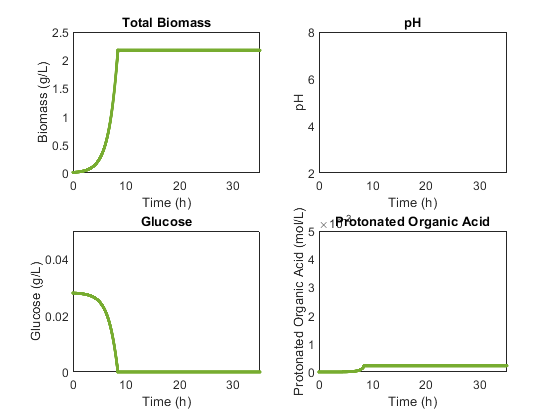

% Script and function to model WT growth and inhibition dynamics in batch culture
% A. Beck, R. Carlson, and T. Gedeon
% May 2022 

clear all
clc

% Define time length and initial conditions, set options, and solve
tspan = [0,... % (h) start time
   35]; % (h) end time
y0 = [0.010000,... % (g/L) initial producer biomass concentration%0.010000,... % (g/L) initial scavenger biomass concentration
    0.028000,... % (mols/L) initial glucose concentration
    0.00000,... % (mols/L) initial acetate concentration
    10^-7];%,...% (mols/L) initial proton concentration
   
options=odeset('AbsTol',1e-12,... % threshold below which value of solution becomes unimportant
      'RelTol',1e-12,... % controls # of correct digits in all solution components except those < than AbsTol
      'MaxStep',1e-2); % upper bound on size of any step taken by the solver
%      'OutputFcn','odeplot'); % plots solution components as they are computed
[t,y]=ode15s(@fun_acecom,tspan,y0,options); % solve ODEs in fun_acecom function below

tau=35; % time scale for figures

%Biomass concentrations  
subplot(2,2,1)
plot(t,y(:,1),'.','color',[0.4667 0.6745 0.1882]) %green
%plot(t,y(:,1),'.','color',[0.8500 0.3250 0.0980]) %orange
hold on
title('Total Biomass')
xlabel('Time (h)')
ylabel('Biomass (g/L)')
axis([0 tau 0 2.5])

% Culture PH
subplot(2,2,2)
plot(t,-log10(y(:,4)),'.','color',[0.4667 0.6745 0.1882] ) %green
%plot(t,-(log10(y(:,4))),'.','color',[0.8500 0.3250 0.0980] ) %orange
plot(t,y(:,4),'.','color',[0.7608 0.5451 0.0471])
hold on
title('pH')
xlabel('Time (h)')
ylabel('pH')
axis([0 tau 2 8]) 

% Glucose concentration
subplot(2,2,3)
plot(t,y(:,2),'.','color',[0.4667 0.6745 0.1882] ) % green
%plot(t,y(:,2),'.','color',[0.8500 0.3250 0.0980] ) % ornage
hold on
title('Glucose')
xlabel('Time (h)')
ylabel('Glucose (g/L)')
axis([0 tau 0 0.05])

% Protonated or total acetate
subplot(2,2,4)
plot(t,y(:,3)./(1+(1./(y(:,4)))*10^(-4.75)),'.','color',[0.4667 0.6745 0.1882] )% green
%plot(t,y(:,3)./(1+f1star),'.','color',[0.8500 0.3250 0.0980] ) % orange
hold on
title('Protonated Organic Acid')
xlabel('Time (h)')
ylabel('Protonated Organic Acid (mol/L)')
axis([0 tau 0 0.005])



% THE END



function dydt = fun_acecom(t,y)


YXGp = 0.43; % (g/g) yield of producer biomass per glucose
YAXp = 0.26;% (g/g)yield of acetate per producer biomass
P0= 0.064; %M 0.0063 (low buffer) 0.064 M (normal buffer)
YH =0.009;% 0.009- 0.0012mol H+/g cdw 
C=10^(-4.75);
D=10^(-7.03);


% Define ODEs
xp = y(1,1); % biomass (of producer)
G = y(2,1);  % glucose
A = y(3,1); % acetate total
H = y(4,1); % H+


f1star= (1/H)*C;

## Equation for growth rate

mumaxp=0.65; %1/h maximum growth rate of WT
KG= 0.005;% 0.5*10^(-5);% M  (It was 0.005 mM) half-saturation constant for glucose substrate

%Ghose and Tyagi acetate inhibition equation
Astar=1.44;% mM
mup = mumaxp*(1000*G/(KG+1000*G))*max([0 (1-((1000*A)/Astar)*1/(1+f1star))]);

% Equations
dydt(1,1) = mup*xp; % ODE for producer biomass concentration
dydt(2,1) = -(1/YXGp)*mup*xp*(1/180); % ODE for glucose concentration
dydt(3,1) = YAXp*mup*xp*(1/60); % ODE for acetate concentration
dydt(4,1) =(mup*xp)*YH/(1+(D*P0)/(D+H)^2 + (C*A)/(C+H)^2); % ODE for H^+ concentration


end